# Test 1: One layer, spherically-symmetric model 

In this notebook the tidal response of **one layer spherically-symmetric model **is computred using LOV3D and compared with results from analytical expressions

clearvars
clc
set(0,'defaulttextInterpreter','latex') 
mfile_name          = mfilename('fullpath');
if contains(mfile_name,'LiveEditorEvaluationHelper')
    mfile_name=matlab.desktop.editor.getActiveFilename;
end
[pathstr,name,ext]  = fileparts(mfile_name);
cd(pathstr);
cd('..')
addpath(genpath(pwd))

## Interior Model 

We consider a one-layer incompressible spherically-symmeric body

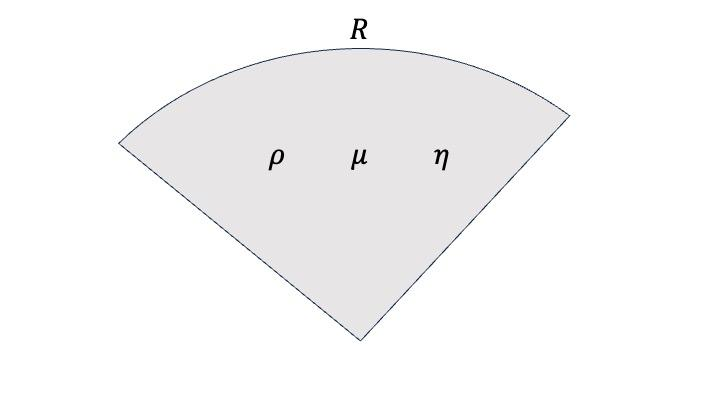

The interior properties can be given in dimensional paramters

Or, alternatively, we can also directly set the non-dimensional parameters: 

mu_eff:  $\mu_{eff}=\frac{\mu}{g_s\rho R}$, 

MaxTime: $\tau=\frac{\omega\eta_0}{\mu_0}$

r_ratio: $\frac{R_c}{R}$

rho_r: $\frac{\rho_c}{\rho}$

%--- WORK IN NONDIMENSIONAL UNITS
% mu_eff=5.2; %effective shear modulus 
% r_ratio=0.001; %core-radius ratio. In this case set to virtually 0 
% rho_r=1; %ratio between core and mantle density
% MaxTime=3.42;
% %MaxTime=3.42e-8;
% rho_av=rho_r*r_ratio^3+(1-r_ratio^3);
% % Build layered interior model 
% %Core layer (1)
% Interior_Model(1).R0= r_ratio; % CMB radius
% Interior_Model(1).rho0= rho_r; % CMB density 
% % Mantle layer (2)
% Interior_Model(2).R0= 1;  %surface radius
% Interior_Model(2).rho0=1; %mantle density 
% Interior_Model(2).mu0=1;  %shear modulus
% Interior_Model(2).MaxTime=MaxTime; %nondimensional Maxwell time, can set to NaN or commented if elastic
% Gg=3/(4*pi)/mu_eff/rho_av^2;
% Interior_Model(2).Gg=3/(4*pi)/mu_eff/rho_av^2; %non-dimensional gravitational constatant
% T=1; % forcing period, it has been normalized to 1
%--- WORK IN DIMENSIONAL UNITS
R0=3389.5;% Radius in km 
rho0=3930;% density in kg/m3
mu0=80e9; % shear modulus in Pa; 
eta0=1e20; % viscosity in Pa.s
G0=6.67430E-11;
%Core layer (1)
Interior_Model(1).R0= 1e-3*R0; % CMB radius
Interior_Model(1).rho0=rho0; % CMB density 
% Mantle layer (2)
Interior_Model(2).R0= R0;  %surface radius
Interior_Model(2).rho0=rho0; %mantle density 
Interior_Model(2).mu0=mu0;  %shear modulus
% Interior_Model(2).eta0=eta0;  %viscosity
% omega0=4.1086E-05; %Mar's orbital frequency
% T=2*pi/omega0; %Mar's orbital period
T = 779.94*3600*24

T = 67386816

omega0 = 2*pi/T

omega0 = 9.3241e-08

% omega0 = 0
% T = 0
% LATERAL VARIATIONS
% Spherically-symmetric model assumed
% compute effective shear modulus
mu_eff=mu0/(rho0^2*(R0*1e3)^2*4/3*pi*G0)

mu_eff = 1.6126

The forcing potential is defined, note that the degree of the forcing can be changed

Forcing(1).Td=T;
Forcing(1).n=2; 
Forcing(1).m=0; 
Forcing(1).F=1;

## Define numerics used to compute the tidal response 

%radial discretization
Numerics.Nlayers = length(Interior_Model); % number of concentric layers. Including the core!
Numerics.method = 'variable'; % method of setting the radial points per layer
Numerics.Nrbase = 200; % depending on the method this will determine the number of points per layer
%code parallelization
Numerics.parallel_sol = 0; % Use a parfor-loop to call get_Love, either 0 or 1
Numerics.parallel_gen = 0; % Calculate potential coupling files and the propagation inside get_solution using parfor-loops, either 0 or 1
% lateral variations
Numerics.perturbation_order = 2; %maximum order to which couplings are considered
Numerics.solution_cutoff = 12; % maximum degree of solution, not used if perturbation order is specified
Numerics.load_couplings = 1; % 0=no loading, 1=loading of specific file, 2=searches for big enough file
Numerics.Nenergy = 12; % maximum degree to which energy dissipation is expanded 
Numerics.rheology_cutoff = 2; % maximum order of difference (so in log) up to which rheology is still used 
[Numerics, Interior_Model] = set_boundary_indices(Numerics, Interior_Model,'verbose');

Inside set_boundary_indices: 
Nrlayer: 0  200
BCindices: 
Nr: 200
 


## Compute the tidal response 

The tidal response is obtained 

% write interior model in the right format for the code
Interior_Model = get_rheology(Interior_Model,Numerics,Forcing);

Viscosity for layer 2 not provided, I will assume the layer is elastic 
Bulk modulus for layer 2 not provided, I will assume the layer is incompressible 
No lateral variations provided for layer 2, I will assume the layer is spherically-symmetric 


[Love_Spectra,y]=get_Love(Interior_Model,Forcing,Numerics,'verbose');

Obtaining Couplings....
Only uniform layers so coupling matrix is zero
------------- INTERIOR MODEL ----------- 
AVERAGE PROPERTIES (dimensional)
Layer#     R[m]    rho[kg.m^{-3}]    mu[Pa]    K[Pa]    eta[Pa.s]
1    3.38950e+00    3.93000e+03    0    -
2    3.38950e+03    3.93000e+03    8.00000e+10    8.00000e+17 
AVERAGE PROPERTIES (non-dimensional)
Layer#     R[-]    rho[-]    mu[-]    K [-]     eta[-]
1    0.001    1    0    -
2    1    1    1    10000000 NaN
RHEOLOGY  VARIATIONS
Shear Modulus
Layer#      (n,m)           amplitude[mu_n^m/mu_0^0]
2    (0,0)   0.00000e+00
Bulk Modulus
Layer#      (n,m)           amplitude[K_n^m/K_0^0]
2    (0,0)   0.00000e+00
Viscosity
Layer#      (n,m)          amplitude[eta_n^m/eta_0^0]
2    (0,0)   0.00000e+00
Complex Shear Modulus
Layer#      (n,m)         amplitude[\hat\mu_n^m/mu_0^0]
2    (0,0)    0.00000e+00
 
----------- FORCING ----------
TIDAL POTENTIAL
Period [s]
6.73868e+07
(n,m)
(2,0)
 
---------

## Compare against analytical expression 

The result obtained with the code is compared againts the analytical expression for k2 (see for example [Matsuyama et al. 2018](https://doi.org/10.1016/j.icarus.2018.04.013) Appendix B1)

$k_n=\frac{2}{2(n-1)} \frac{1}{1+\hat\mu_n}$; $h_n=\frac{2n+1}{2(n-1)}\frac{1}{1+\hat\mu_n}$ 

with 

$\hat\mu_n=\frac{2n^2+4n+3}{n}\hat\mu_{eff}$ with  $\hat\mu_{eff}=\frac{\hat\mu}{\rho g R}=\mu_{eff}\left(1-\frac{i}{\hat\tau}\right)^{-1}$

% obtain the Fourier-transformed effective shear modulus
mu_eff_hat=mu_eff*Interior_Model(2).muC;
% compute Love numbers using analytical expression
n=Forcing.n; 
mu_n=(2*n^2+4*n+3)/n*mu_eff_hat;
k2_analytic=1/(1+mu_n)*3/2/(n-1);
h2_analytic=1/(1+mu_n)*(2*n+1)/2/(n-1);
% display results
disp(['k Love number analytical expression: ' num2str(k2_analytic)])

k Love number analytical expression: 0.091911


disp(['k Love number LOV3D: ' num2str(Love_Spectra.k)])

k Love number LOV3D: 0.091911


disp(['Normalized difference: ' num2str((Love_Spectra.k-k2_analytic)/k2_analytic*100)  '%'])

Normalized difference: -4.3909e-06%


disp(['h Love number analytical expression: ' num2str(h2_analytic)])

h Love number analytical expression: 0.15318


disp(['h Love number LOV3D: ' num2str(Love_Spectra.h)])

h Love number LOV3D: 0.15318


disp(['Normalized difference: ' num2str((Love_Spectra.h-h2_analytic)/h2_analytic*100)  '%'])

Normalized difference: -3.7046e-06%


% Interior Model C (Beuthe 2013)
Interior_Model_Multi(1).R0 = 1e-3*R0; % CMB in km 
Interior_Model_Multi(1).rho0 = rho0; % average density in kg m^-3
% Interior_Model values for core
Interior_Model_Multi(2).R0 = 1550; % outer radius of this layer
Interior_Model_Multi(2).rho0 = 7200; % density in kg m^-3
Interior_Model_Multi(2).Ks0 = 170e9; % bulk modulus in Pa
Interior_Model_Multi(2).mu0 = 70e9; % shear modulus in Pa
Interior_Model_Multi(2).eta0 = 1e20; % viscosity in Pa s
% Interior_Model values for mantle
Interior_Model_Multi(3).R0 = 3334.5; % outer radius of this layer
Interior_Model_Multi(3).rho0 = 3500; % density in kg m^-3
Interior_Model_Multi(3).Ks0 = 105e9; % bulk modulus in Pa
Interior_Model_Multi(3).mu0 = 60e9; % shear modulus in Pa
Interior_Model_Multi(3).eta0 = 1e20; % viscosity in Pa s
% Interior_Model values for crust
Interior_Model_Multi(4).R0 = 3389.5; % outer radius of this layer
Interior_Model_Multi(4).rho0 = 2900; % density in kg m^-3
Interior_Model_Multi(4).Ks0 = 43e9; % bulk modulus in Pa
Interior_Model_Multi(4).mu0 = 30e9; % shear modulus in Pa
Interior_Model_Multi(4).eta0 = 1e20; % viscosity in Pa s

## Define forcing

The forcing potential is defined

Forcing(1).Td=T;
Forcing(1).n=2; 
Forcing(1).m=0; 
Forcing(1).F=1;

## Define numerics used to compute the tidal response 

%radial discretization
Numerics.Nlayers = length(Interior_Model_Multi); % number of concentric layers. Including the core!
Numerics.method = 'variable'; % method of setting the radial points per layer, here fixed number of layers
Numerics.Nrbase = 2000; % depending on the method this will determine the number of points per layer
%code parallelization
Numerics.parallel_sol = 0; % Use a parfor-loop to call get_Love, either 0 or 1
Numerics.parallel_gen = 0; % Calculate potential coupling files and the propagation inside get_solution using parfor-loops, either 0 or 1
% lateral variations
Numerics.perturbation_order = 2; %maximum order to which couplings are considered
Numerics.solution_cutoff = 12; % maximum degree of solution, not used if perturbation order is specified
Numerics.load_couplings = 0; % 0=no loading, 1=loading of specific file, 2=searches for big enough file
Numerics.Nenergy = 12; % maximum degree to which energy dissipation is expanded 
Numerics.rheology_cutoff = 2; % maximum order of difference (so in log) up to which rheology is still used 
[Numerics, Interior_Model] = set_boundary_indices(Numerics, Interior_Model_Multi,'verbose');

Inside set_boundary_indices: 
Nrlayer: 0  2000  2000  2000
BCindices: 2001  4001  6001
Nr: 6000
 


## Compute the tidal response 

The tidal response is obtained for models A and B 

% write interior model in the right format for the code
Interior_Model_Multi= get_rheology(Interior_Model_Multi,Numerics,Forcing);

No lateral variations provided for layer 2, I will assume the layer is spherically-symmetric 
No lateral variations provided for layer 3, I will assume the layer is spherically-symmetric 
No lateral variations provided for layer 4, I will assume the layer is spherically-symmetric 


[Love_Spectra_multi,y]=get_Love(Interior_Model_Multi,Forcing,Numerics,'verbose');

Obtaining Couplings....
Only uniform layers so coupling matrix is zero
------------- INTERIOR MODEL ----------- 
AVERAGE PROPERTIES (dimensional)
Layer#     R[m]    rho[kg.m^{-3}]    mu[Pa]    K[Pa]    eta[Pa.s]
1    3.38950e+00    3.93000e+03    0    -
2    1.55000e+03    7.20000e+03    7.00000e+10    1.70000e+11 1.00000e+20
3    3.33450e+03    3.50000e+03    6.00000e+10    1.05000e+11 1.00000e+20
4    3.38950e+03    2.90000e+03    3.00000e+10    4.30000e+10 1.00000e+20
AVERAGE PROPERTIES (non-dimensional)
Layer#     R[-]    rho[-]    mu[-]    K [-]     eta[-]
1    0.001    1.3552    0    -
2    0.45729    2.4828    2.3333    5.6667 49.4657
3    0.98377    1.2069    2    3.5 49.4657
4    1    1    1    1.4333 49.4657
RHEOLOGY  VARIATIONS
Shear Modulus
Layer#      (n,m)           amplitude[mu_n^m/mu_0^0]
2    (0,0)   0.00000e+00
Layer#      (n,m)           amplitude[mu_n^m/mu_0^0]
3    (0,0)   0.00000e+00
Layer#      (n,m)           amplitude[mu_n^m/mu_0^0]
4    (0,0) 

## Comparison of k2 Love numbers

The values obtained with the spherically-symmetric poroviscoealstic [code](https://github.com/mroviranavarro/Poroviscoelastic_Tides) are: 

- Model A: 0.733721707307109 - 0.015123675091503i

- Model B: 0.611841605660674 - 0.015009557001099i

- Model C: should lead to -Im(k2)=0.015 as stated in [Beuthe et al. 2013](https://www.sciencedirect.com/science/article/pii/S0019103512004745?casa_token=xg0XfpmaHT4AAAAA:Qau6ppdURvhX_Vgm_NiDZVwEtERNnqcosVviHYGaLIHJLBugG7ZgBEnHNPG921Qc5SZAktQ6kw)

disp(['k_2 Model A ' num2str(Love_Spectra_multi.k)])

k_2 Model A 0.096192-0.0005929i


% Generate vector of viscosity values
eta_vect = logspace(-10, 8, 20) * 1e20;

Unrecognized function or variable 'eta0'.

mu_vect =  logspace(-1, 1, 10) * 60e9;
% T_vect = logspace(-1, log10(3.1e13), 10)
% eta_vect = mu_vect
% Preallocate arrays for storing Love numbers
k_real_values = zeros(length(eta_vect), 1);
k_imag_values = zeros(length(eta_vect), 1);
h_real_values = zeros(length(eta_vect), 1);
h_imag_values = zeros(length(eta_vect), 1);

% Interior Model C (Beuthe 2013)
Interior_Model_loop(1).R0 = 1e-3*R0; % CMB in km 
Interior_Model_loop(1).rho0 = rho0; % average density in kg m^-3
% Interior_Model values for core
Interior_Model_loop(2).R0 = 1550; % outer radius of this layer
Interior_Model_loop(2).rho0 = 7200; % density in kg m^-3
Interior_Model_loop(2).Ks0 = 170e9; % bulk modulus in Pa
Interior_Model_loop(2).mu0 = 70e9; % shear modulus in Pa
Interior_Model_loop(2).eta0 = 1e20; % viscosity in Pa s
% Interior_Model values for mantle
Interior_Model_loop(3).R0 = 3334.5; % outer radius of this layer
Interior_Model_loop(3).rho0 = 3500; % density in kg m^-3
Interior_Model_loop(3).Ks0 = 105e9; % bulk modulus in Pa
Interior_Model_loop(3).mu0 = 60e9; % shear modulus in Pa
Interior_Model_loop(3).eta0 = 1e20; % viscosity in Pa s
% Interior_Model values for crust
Interior_Model_loop(4).R0 = 3389.5; % outer radius of this layer
Interior_Model_loop(4).rho0 = 2900; % density in kg m^-3
Interior_Model_loop(4).Ks0 = 43e9; % bulk modulus in Pa
Interior_Model_loop(4).mu0 = 30e9; % shear modulus in Pa
Interior_Model_loop(4).eta0 = 1e20; % viscosity in Pa s
% Loop over viscosity values
for j = 1:length(eta_vect)
    % Update dynamic viscosity in the Interior structure
    Interior_Model_loop(2).eta0 = eta_vect(j);
    Interior_Model_loop(3).eta0 = eta_vect(j);
    Interior_Model_loop(4).eta0 = eta_vect(j);
    % Interior_Model_loop(3).mu0 = mu_vect(j);
    % Forcing(1).Td = T_vect(j);

    % Compute updated rheology
    Interior_U = get_rheology(Interior_Model_loop, Numerics, Forcing);

    % Calculate Love numbers
    [Love_Spectra, y] = get_Love(Interior_U, Forcing, Numerics);

    % Store Love numbers (real and imaginary parts)
    k_real_values(j) = real(Love_Spectra.k);
    k_imag_values(j) = imag(Love_Spectra.k);
    h_real_values(j) = real(Love_Spectra.h);
    h_imag_values(j) = imag(Love_Spectra.h);

    % Display results
    disp([eta_vect(j)])
    disp(['k Love number LOV3D (real): '  num2str(real(Love_Spectra.k)) ' (imag): '  num2str(imag(Love_Spectra.k))])
    disp(['h Love number LOV3D (real): '  num2str(real(Love_Spectra.h)) ' (imag): '  num2str(imag(Love_Spectra.h))])
end

% Plot k with respect to mu (real and imaginary parts)
figure;
semilogx(eta_vect, k_real_values, '-o', 'DisplayName', 'Real part');
hold on;
semilogx(eta_vect, k_imag_values, '--s', 'DisplayName', 'Imaginary part');
%xlabel('eta [Pa s]');
xlabel('Eta [GPa]');
ylabel('k Love number');
title('k Love number vs. eta ');
%title('k Love number vs. Mu');
legend('show');
grid on;

% Plot h with respect to mu (real and imaginary parts)
figure;
semilogx(eta_vect, h_real_values, '-o', 'DisplayName', 'Real part');
hold on;
semilogx(eta_vect, h_imag_values, '--s', 'DisplayName', 'Imaginary part');
%xlabel('eta [Pa s]');
xlabel('Eta [GPa]');
ylabel('h Love number');
title('h Love number vs. eta');
%title('h Love number vs. Mu');
legend('show');
grid on;




Interior_Model = get_rheology(Interior_Model,Numerics,Forcing);
[Love_Spectra,y]=get_Love(Interior_Model,Forcing,Numerics,'verbose');